clear;

% inputs
CMF_type =  '1931_full';    % CIE CMF（color matching function, CMF）
loadMat = load('sample_data\ARAD_1K_0001.mat');  % msi data path
msi_read = loadMat.cube;
pixelMax = max(msi_read(:));
band_name = 400:10:700;  % msi band sequence
NUM_BAND = length(band_name);

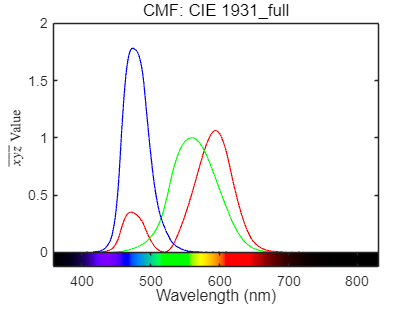


% visualize CMF
[lambda, x_bar, y_bar, z_bar] = colorMatchFcn(CMF_type);
fig_cmf = figure;
plot(lambda, x_bar, 'r', lambda, y_bar, 'g', lambda, z_bar, 'b','LineWidth',1);
ax = gca;
ax.Position = [0.13,0.183908045977011,0.775,0.741091954022988];
ax.FontSize = 12;
title(['CMF: CIE ',CMF_type],'Interpreter','none','FontSize',14);
ylabel('$\bar{x}\bar{y}\bar{z}$ Value','FontSize',12,'Interpreter','latex');
spectrumLabel(gca,CMF_type);
xlabel('Wavelength (nm)','FontSize',12);
set(gca,'FontSize',12);
fig_cmf.Position = [422,266,825,609];

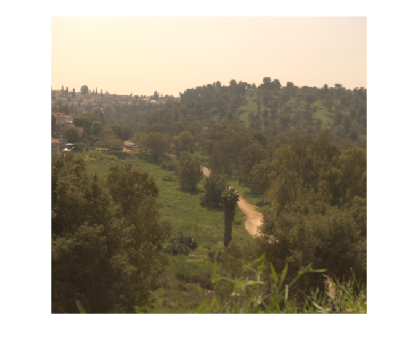


% combine all spectral images and synthesize an RGB image
[rowNum,colNum,bandNum] = size(msi_read);
msi_read_2D = reshape(double(msi_read),rowNum*colNum,bandNum);  % flatten to 2D
msi_refl_2D = msi_read_2D./pixelMax;  % normalize into reflectance
spectr_xyzbar = squeeze(spectrumXYZ(band_name,CMF_type));  % read CMF data as spectral xyzbar
XYZ_2D = (spectr_xyzbar'*msi_refl_2D')';  % convert spectral xyzbar to XYZ color space
XYZ = reshape(XYZ_2D,rowNum,colNum,3);  % recover XYZ cube
XYZ = XYZ/max(XYZ(:));  % normalize

% convert XYZ to 8-bit RGB image in sRGB color space
synth_rgb = im2uint8(xyz2rgb(XYZ,'WhitePoint','d65','colorspace','srgb'));

figure;
imshow(synth_rgb);

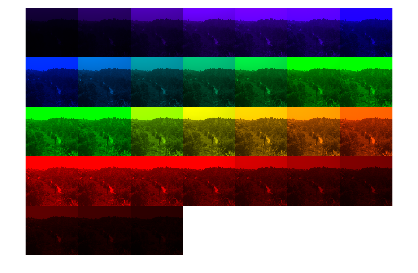

% synthesize single band RGB image
for i_band = 1:NUM_BAND
    synth_X(:,:,i_band) = spectr_xyzbar(i_band,1)*double(msi_read(:,:,i_band))/pixelMax;
    synth_Y(:,:,i_band) = spectr_xyzbar(i_band,2)*double(msi_read(:,:,i_band))/pixelMax;
    synth_Z(:,:,i_band) = spectr_xyzbar(i_band,3)*double(msi_read(:,:,i_band))/pixelMax;
    synth_XYZ_band(:,:,:,i_band) = cat(3,synth_X(:,:,i_band),synth_Y(:,:,i_band),synth_Z(:,:,i_band));
    msi2rgb(:,:,:,i_band) = im2uint8(xyz2rgb(synth_XYZ_band(:,:,:,i_band),'whitepoint','d65','colorspace','srgb'));
end

% show by concat
[H, W, C, B] = size(msi2rgb);
n_col = 5;  % number of images per row
n_row = ceil(B / n_col);

% filling with white patches
N_fill = n_row * n_col - B;
if N_fill > 0
    filler = ones(H, W, C, N_fill, 'like', msi2rgb) * 255;
    msi2rgb_cat = cat(4, msi2rgb, filler);
end

% reshape into (n_row, n_col, H, W, 3)
tmp = permute(msi2rgb_cat, [4, 1, 2, 3]);
tmp = reshape(tmp, [n_row, n_col, H, W, C]);
% reshape into (W*n_col, H*n_row, C)
tmp = permute(tmp, [4, 1, 3, 2, 5]);            
rgb_grid = reshape(tmp, [W*n_row, H*n_col, C]);
rgb_grid = permute(rgb_grid,[2, 1, 3]);

% show stacked colorized msi
figure;
imshow(rgb_grid);


% oberseve with sliceViewer
figure;
sliceViewer(permute(msi2rgb,[1,2,4,3]));